# Лабораторная работа №3

# Исследование резонанса напряжений

## Цель работы: 

Получение навыков эксперементального исследования цепей однофазного синусоидального тока.

## Ответы на вопросы подготовки:

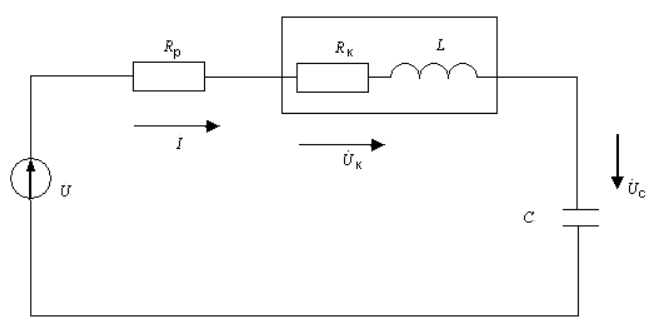

## Теоретический расчет:

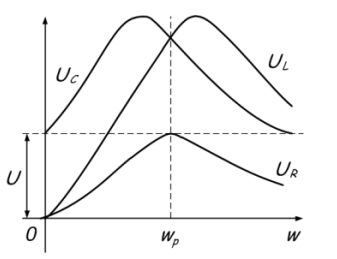

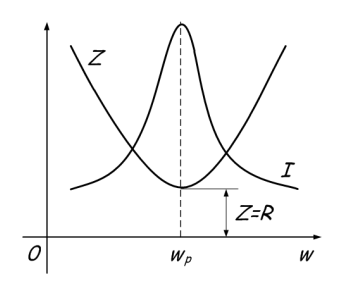$$

R_K = 2;
L = 20e-3;
C = 2e-6;
U = 3;
fi = [100;310;509;650;801;1538;4013];

Для Q=2.5

Q = 2.5;
R_P = sqrt(L/C)/Q;
omeg = 2.*pi.*fi;
X_L = R_K+i.*L.*omeg;
X_C = 1./(i.*C.*omeg);
Z = X_C+X_L+R_P;
I = U./Z;
U_L = X_L.*I;
U_C = X_C.*I;
U_P = R_P.*I;

Расчет и построение графика зависимости угла $\phi_{\mathrm{ВХ}}$ от частоты

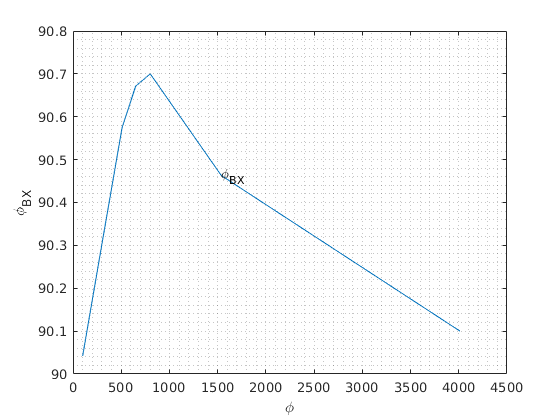

fi_BX = atand((U_L-U_C)./((R_P+R_K).*I));
plot(fi,abs(fi_BX))
text(fi(6),abs(fi_BX(6)),'\phi_B_X');
xlabel('\phi');
ylabel('\phi_B_X');
grid minor;
hold off;

Построение графика зависимости напряжения от частоты

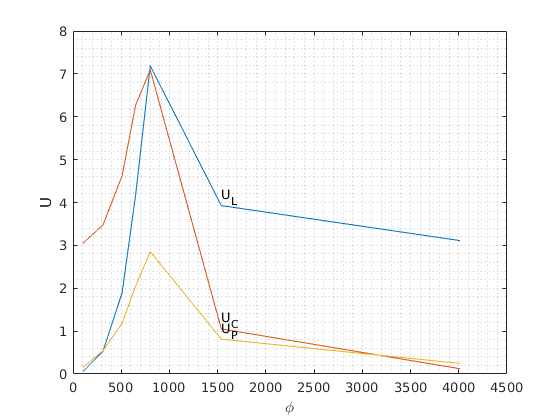

plot(fi,abs(U_L))
text(fi(6)+.2,abs(U_L(6))+.2,'U_L');
hold on;
plot(fi,abs(U_C))
text(fi(6)+.2,abs(U_C(6))+.2,'U_C');
hold on;
plot(fi,abs(U_P))
text(fi(6)+.2,abs(U_P(6))+.2,'U_P');
xlabel('\phi');
ylabel('U');
grid minor;
hold off;

Построение графика зависимости тока от частоты

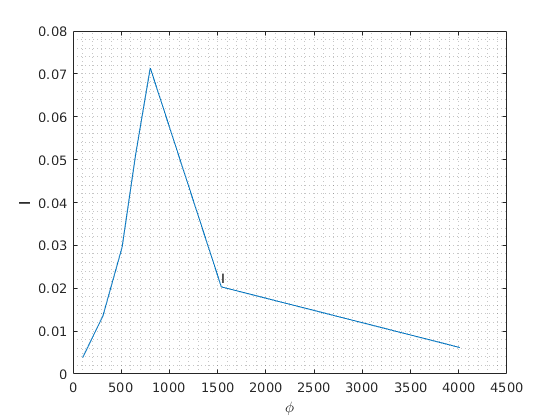

plot(fi,abs(I))
grid minor;
xlabel('\phi');
ylabel('I');
text(fi(6),abs(I(6))+abs(I(6))*.1,'I');

Для Q=5

Q = 5;
R_P = sqrt(L/C)/Q;
omeg = 2.*pi.*fi;
X_L = R_K+i.*L.*omeg;
X_C = 1./(i.*C.*omeg);
Z = X_C+X_L+R_P;
I = U./Z;
U_L = X_L.*I;
U_C = X_C.*I;
U_P = R_P.*I;

Расчет и построение графика зависимости угла $\phi_{\mathrm{ВХ}}$ от частоты

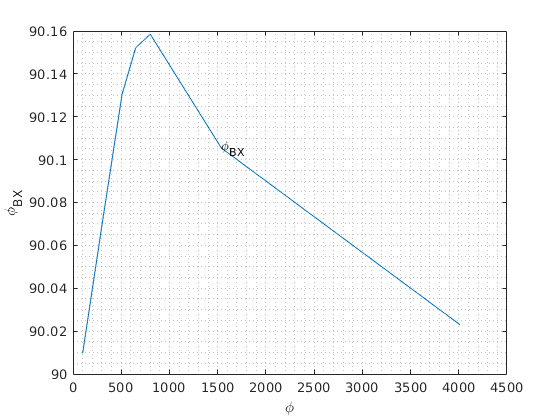

fi_BX = atand((U_L-U_C)./((R_P+R_K).*I));
plot(fi,abs(fi_BX))
text(fi(6),abs(fi_BX(6)),'\phi_B_X');
xlabel('\phi');
ylabel('\phi_B_X');
grid minor;

Построение графика зависимости напряжения от частоты

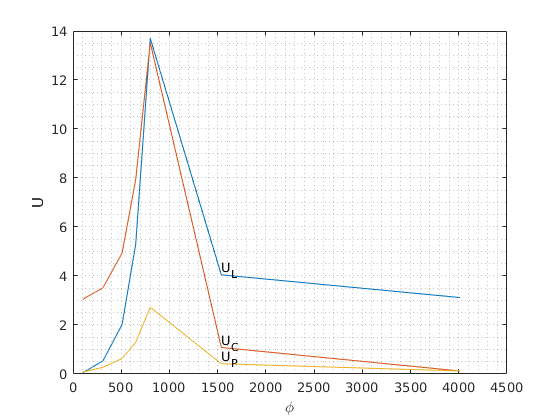

plot(fi,abs(U_L))
text(fi(6)+.2,abs(U_L(6))+.2,'U_L');
hold on;
plot(fi,abs(U_C))
text(fi(6)+.2,abs(U_C(6))+.2,'U_C');
hold on;
plot(fi,abs(U_P))
text(fi(6)+.2,abs(U_P(6))+.2,'U_P');
xlabel('\phi');
ylabel('U');
grid minor;
hold off;

Построение графика зависимости тока от частоты

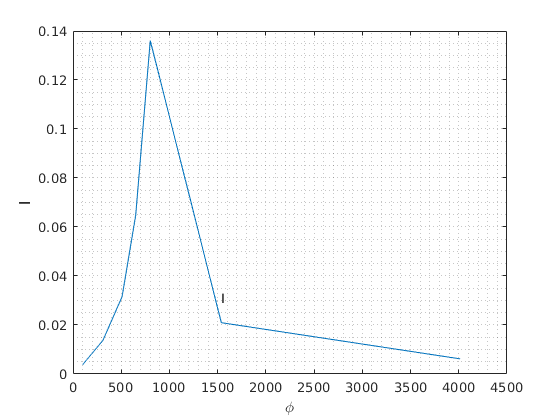

plot(fi,abs(I))
grid minor;
xlabel('\phi');
ylabel('I');
text(fi(6),abs(I(6))+.01,'I');

## Оформление результатов работы:

Результаты измерений:

R_K = 2;
U = 3;

При $Q=2\ldotp 5$

Q_1 = table(...
    [100;310;509;650;801;1538;4013],...
    [0.16;0.57;1.4;2;1.6;0.56;0.2],...
    [3.11;3.72;5.5;6.12;4.04;0.74;0.1],...
    [0;0.75;3.2;5.75;5.8;3.63;3.1],...
    [0;0.75;3.2;5.75;5.8;3.63;3.1],...
    [-87;-78;-58;-10;46;78;86],...
    [4e-3;14.6e-3;35.9e-3;51e-3;41.15e-3;14.45e-3;5.3e-3],...
    'VariableNames',{'fi','U_R','U_C','U_K','U_L','fi_BX','I'}...
)

Q_1 = 7×7 table
     fi     U_R     U_C     U_K     U_L     fi_BX       I   
    ____    ____    ____    ____    ____    _____    _______

     100    0.16    3.11       0       0     -87       0.004
     310    0.57    3.72    0.75    0.75     -78      0.0146
     509     1.4     5.5     3.2     3.2     -58      0.0359
     650       2    6.12    5.75    5.75     -10       0.051
     801     1.6    4.04     5.8     5.8      46     0.04115
    1538    0.56    0.74    3.63    3.63      78     0.01445
    4013     0.2     0.1     3.1     3.1      86      0.0053


При $Q=5$

Q_2 = table(...
    [100;310;509;605;801;1538;4013],...
    [3.96e-3;14.1e-3;38e-3;67.4e-3;60.2e-3;15.1e-3;5.2e-3],...
    'VariableNames',{'fi' 'I'}...
)

Q_2 = 7×2 table
     fi        I   
    ____    _______

     100    0.00396
     310     0.0141
     509      0.038
     605     0.0674
     801     0.0602
    1538     0.0151
    4013     0.0052


1 По экспериментальным данным таблицы построить резонансные кривы

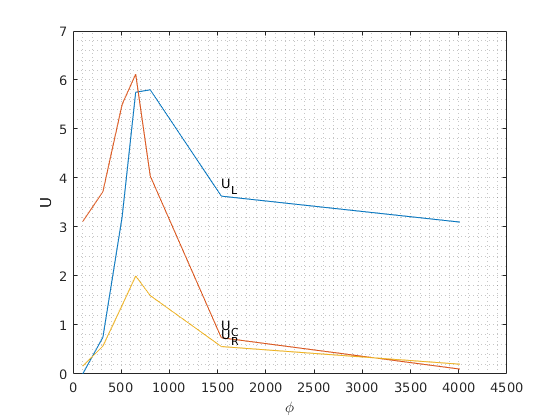

plot(Q_1{:,'fi'},Q_1{:,'U_L'})
text(Q_1{6,'fi'}+.2,Q_1{6,'U_L'}+.2,'U_L');
hold on;
plot(Q_1{:,'fi'},Q_1{:,'U_C'})
text(Q_1{6,'fi'}+.2,Q_1{6,'U_C'}+.2,'U_C');
hold on;
plot(Q_1{:,'fi'},Q_1{:,'U_R'})
text(Q_1{6,'fi'}+.2,Q_1{6,'U_R'}+.2,'U_R');
xlabel('\phi');
ylabel('U');
grid minor;
hold off;

Построение графика зависимости тока от частоты

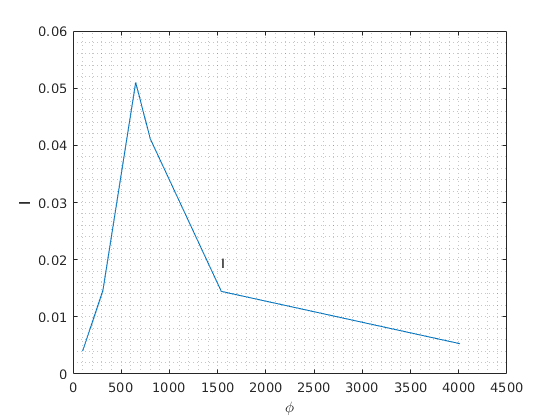

plot(Q_1{:,'fi'},Q_1{:,'I'})
text(Q_1{6,'fi'},Q_1{6,'I'}+.005,'I');
xlabel('\phi');
ylabel('I');
grid minor;

2 Рассчитать  зависимости  $\frac{I}{I_0 }=F\left(\frac{f}{f_0 }\right)$для  добротностей $Q=2\ldotp 5$ и $Q=5$. Построить графики зависимостей.

Q=2.5

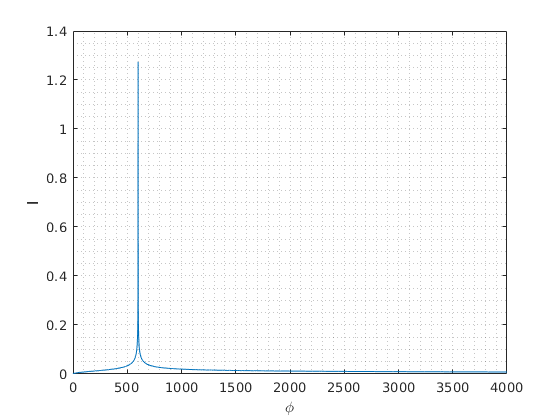

Q=2.5;
I_0 = Q_1{4,'I'};
fi_0 = Q_1{4,'fi'};
F = @(fi) I_0./sqrt(1+Q.^2.*(fi./fi_0-fi_0./fi));
plot(0:4000,abs(F(0:4000)))
grid minor;
xlabel('\phi')
ylabel('I')

Q=5

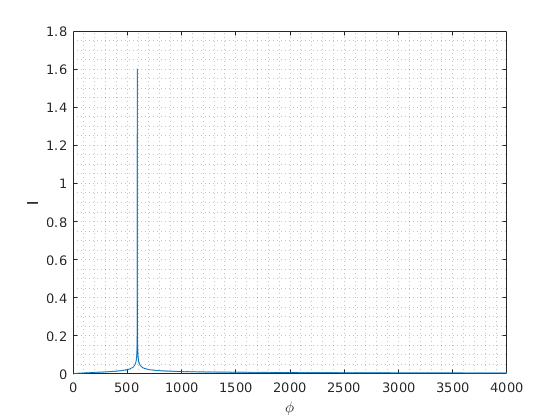

Q=5;
I_0 = Q_2{4,'I'};
fi_0 = Q_2{4,'fi'};
F = @(fi) I_0./sqrt(1+Q.^2.*(fi./fi_0-fi_0./fi));
plot(0:4000,abs(F(0:4000)))
grid minor;
xlabel('\phi')
ylabel('I')

4.3.3  Определить  по  экспериментальным  данным резонансную частоту по максимальному значению тока в цепи при неизменном входном напряжении.

max(Q_1{:,'I'})

ans = 0.0510

4.3.4 Рассчитать и построить график фазочастотной зависимости зависимости;


$$\phi_{\mathrm{вх}} =\mathrm{arctg}\left\lbrack \frac{\left(U_L -U_C \right)}{\left(R_P +R_K \right)I}\right\rbrack$$


При Q=2.5

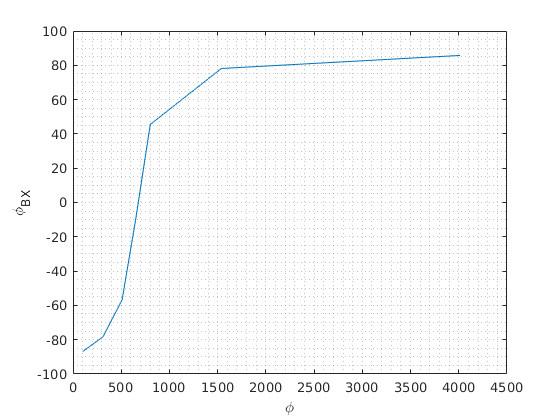

R_P = 40;
fi_BX = atan((Q_1{:,'U_L'}-Q_1{:,'U_C'})./((R_P+R_K).*Q_1{:,'I'}))./pi.*180;
plot(Q_1{:,'fi'},fi_BX)
grid minor;
xlabel('\phi')
ylabel('\phi_B_X')

Расчет мощностей при резонансе.

полная мощность при Q = 2.5

S = Q_1{4,'I'}*U

S = 0.1530

полная мощность при Q = 5

S = Q_2{4,'I'}*U

S = 0.2022

Вывод: Я получил навыки эксперементального исследования цепей однофазного синусоидального тока.